# 1.1.08. Создание временных рядов

**Самостоятельная работа**

Для лабораторной работы вам нужно сгенерировать зашумленный синусоидальный сигнал.

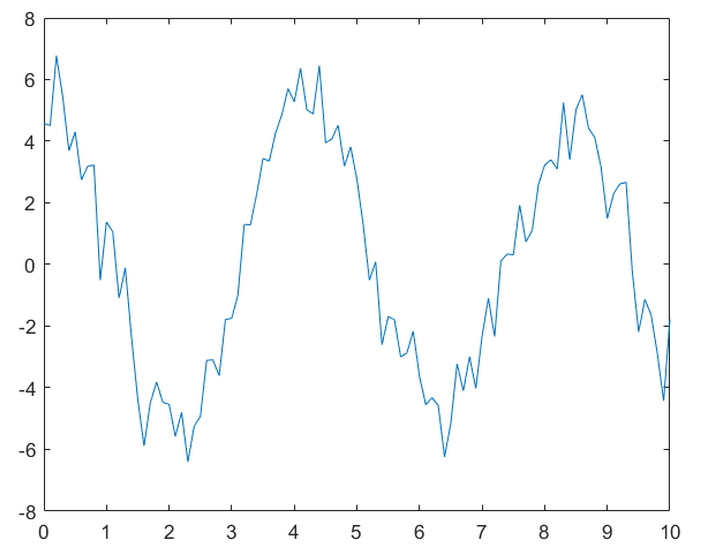

1. Создайте вектор-столбец времени `t` со значениями от `0` до `10` включительно с шагом `0.1`

t = (0:0.1:10)'

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


2. Создайте синусоидальный сигнал - вектор `y`, по следующей формуле:


$$y=5\mathrm{sin}\left(1\ldotp 5t+\frac{\pi }{2}\right)$$


y = 5*sin(1.5*t+pi/2)

y =     5.0000
    4.9439
    4.7767
    4.5022
    4.1267
    3.6584
    3.1080
    2.4879
    1.8118
    1.0950


3. Сгенерируйте шум - вектор-столбец случайно распределенных по нормальному закону значений. Запишите его в переменную n. Вектор `n` должен содержать столько же элементов, сколько и вектор `t` (подсказка: `randn(...,...), length()`)

n = randn(length(t), 1)

n =    -0.4140
   -0.4383
    2.0034
    0.9510
   -0.4320
    0.6489
   -0.3601
    0.7059
    1.4158
   -1.6045


4. Зашумите сигнал: запишите в переменную `yn` сумму сигнала `y` и шума `n`

yn = y + n;

5. Постройте простейший график зашумленного сигнала `yn` от времени `t` (подсказка: `plot(...,...)`)

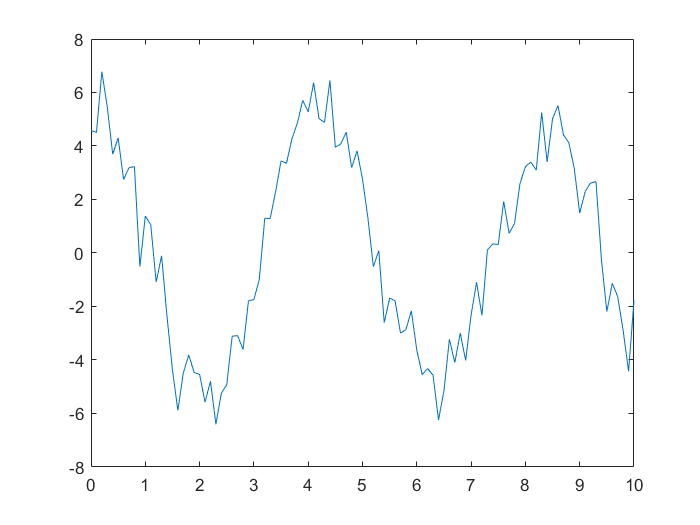

plot(t, yn)

*2018 © ЦИТМ Экспонента*